%{ 
ES115 Engineering Computer Applications 
Module 1 Project: Community Solar Billing Simulator

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: Match 28, 2026

Purpose:
The purpose of this project is to compare two solar billing plans. It uses mathimatical models
in order to calculate monthly costs based on energy usage. It specifically compares a simple 
flat-rate plan (Plan A) against a more complex "piecewise" plan (Plan B) that changes its price 
after a certain amount of usage.

Inputs (that we know):
- Usage Range (x): A set of energy usage values from 0 to 800 kWh.
- Step Size: Increments of 25 kWh per calculation point.
- Plan A Coefficients: Slope ($15$) and Base Fee ($25$).
- Plan B Coefficients: Initial Slope ($12$), Base Fee ($40$), and Adjusted Slope ($14$) after 
the threshold.
- Threshold Value: The "break" point at 400 kWh where Plan B's rate changes.

Outputs: 
- Plan A Bill Vector: Total monthly costs for Plan A across the usage range.
- Plan B Bill Vector: Total monthly costs for Plan B across the usage range.
- Break-even Point: The specific usage level (5 kWh) where both plans are equal in cost.
- Comparison Table: A 10-row summary table showing usage vs. costs.
- Visualization: A multi-line graph highlighting the intersection and the 400 kWh break.

Engineering Workflows & Algorithims:
- Vector Initialization: Pre-allocating memory for the planB results using zeros to improve 
computational efficiency.
- Linear Modeling: Applying a standard $y = mx + b$ linear equation for Plan A.
- Piecewise Logic (Conditional Branching): An if-else algorithm within a for loop to apply 
different mathematical rules to Plan B based on whether usage is above or below the 400 kWh 
limit.
- Intersection Analysis: Algebraic solving of the equations to determine the "Equivalence Point."
- Data Downsampling: Using linear spacing logic to select a subset of data (10 rows) from a 
larger dataset for the final table.

MATLAB Tools and Functions Used:
- linspace: Generates evenly spaced indices to select table rows.
- table: Packages vectors into a structured, readable data format.
- plot: Generates the primary visual comparison.
- xline: Creates a vertical reference line to mark the 400 kWh "break."
- hold on/off: Allows multiple plots (Plan A and Plan B) to exist on a single set of axes.
- fprintf: Formats the final text recommendation with variables embedded in the string.
- legend & grid: Enhances plot readability for documentation purposes.

Project Reflection:
- I learned about logic for pricewise modeling using if-else statments in
order to use loops for handling realworld complex rules.
- The project allowed me to have a deeper understanding of data
vizualization and comparison using comands such as "xline" and "plot" to
make a visual graph on the project.
%}


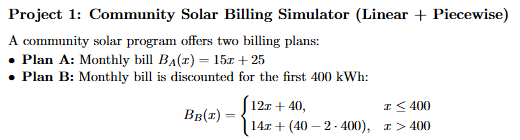


x = (0:25:800)';

planA = 15 * x + 25;

planB = zeros(size(x));
for i = 1:length(x)
    if x(i) <= 400
        planB(i) = 12 * x(i) + 40;
    else
        planB(i) = 14 * x(i) + (40 - 2 * 400);
    end
end

intersection_usage = 5; 
intersection_cost = 15 * intersection_usage + 25;

indices = round(linspace(1, length(x), 10));
Usage_kWh = x(indices);
Bill_A = planA(indices);
Bill_B = planB(indices);
comparisonTable = table(Usage_kWh, Bill_A, Bill_B);

disp('--- Community Solar Billing Comparison ---');

--- Community Solar Billing Comparison ---


disp(comparisonTable);

    Usage_kWh    Bill_A    Bill_B
    _________    ______    ______

         0          25        40 
       100        1525      1240 
       175        2650      2140 
       275        4150      3340 
       350        5275      4240 
       450        6775      5540 
       525        7900      6590 
       625        9400      7990 
       700       10525      9040 
       800       12025     10440 



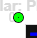


figure('Color', 'w');
plot(x, planA, 'b-', 'LineWidth', 2); hold on;
plot(x, planB, 'r--', 'LineWidth', 2);

xline(400, 'k:', 'Break at 400 kWh', 'LabelVerticalAlignment', 'bottom');
plot(intersection_usage, intersection_cost, 'ko', 'MarkerFaceColor', 'g');

grid on;
xlabel('Energy Usage (kWh)');
ylabel('Monthly Bill ($)');
title('Community Solar: Plan A vs Plan B');
legend('Plan A (15x + 25)', 'Plan B (Piecewise)', 'Location', 'northwest');


fprintf('--- Recommendation ---\n');

--- Recommendation ---


fprintf('Equivalence Point: At %d kWh, both plans cost $%d.\n', intersection_usage, intersection_cost);

Equivalence Point: At 5 kWh, both plans cost $100.


fprintf('1. Choose Plan B for usage between %d and 400 kWh.\n', intersection_usage);

1. Choose Plan B for usage between 5 and 400 kWh.


fprintf('2. Plan B remains cheaper for almost the entire range provided.\n');

2. Plan B remains cheaper for almost the entire range provided.
